# Homework Assignment 4 : Sensor & Signal Conditioning

## Objective : 

การบ้านนี้ถูกออกแบบมาเพื่อให้ผู้เรียนได้จำลองเซนเซอร์ Strain Gauge และนำไปประยุกต์ให้ใช้ได้ในบริบทของการอ่านค่าเซนเซอร์ที่เหมาะสม

## หมายเหตุ

ไฟล์สำหรับการส่งการบ้านให้ตั้งชื่อให้อยู่ในรูปแบบดังต่อไปนี้

FRA231_HWลำดับ_รุ่น-รหัสนักศึกษา_รุ่น-รหัสนักศึกษา.zip

ตัวอย่างเช่น: 

นักศึกษารุ่น 6 รหัส 63340200003 ทำงานคู่กับนักศึกษารุ่น 7 รหัส 64340200023

ให้ตั้งชื่อไฟล์ดังนี้ FRA231_HW2_6-3_7-23.zip

## โจทย์ : 

กำหนดให้ระบบทางกายภาพประกอบไปด้วยคานปลายยื่น (Cantilever beam) ที่มีแรงกระทำ $F$ที่ปลายของคาน โดยที่แรงนั้นจะเปลี่ยนแปลงอยู่ในช่วง $0\ldotp 5$ ถึง $1\ldotp 0\;\left\lbrack \mathrm{N}\right\rbrack$ เท่านั้น 

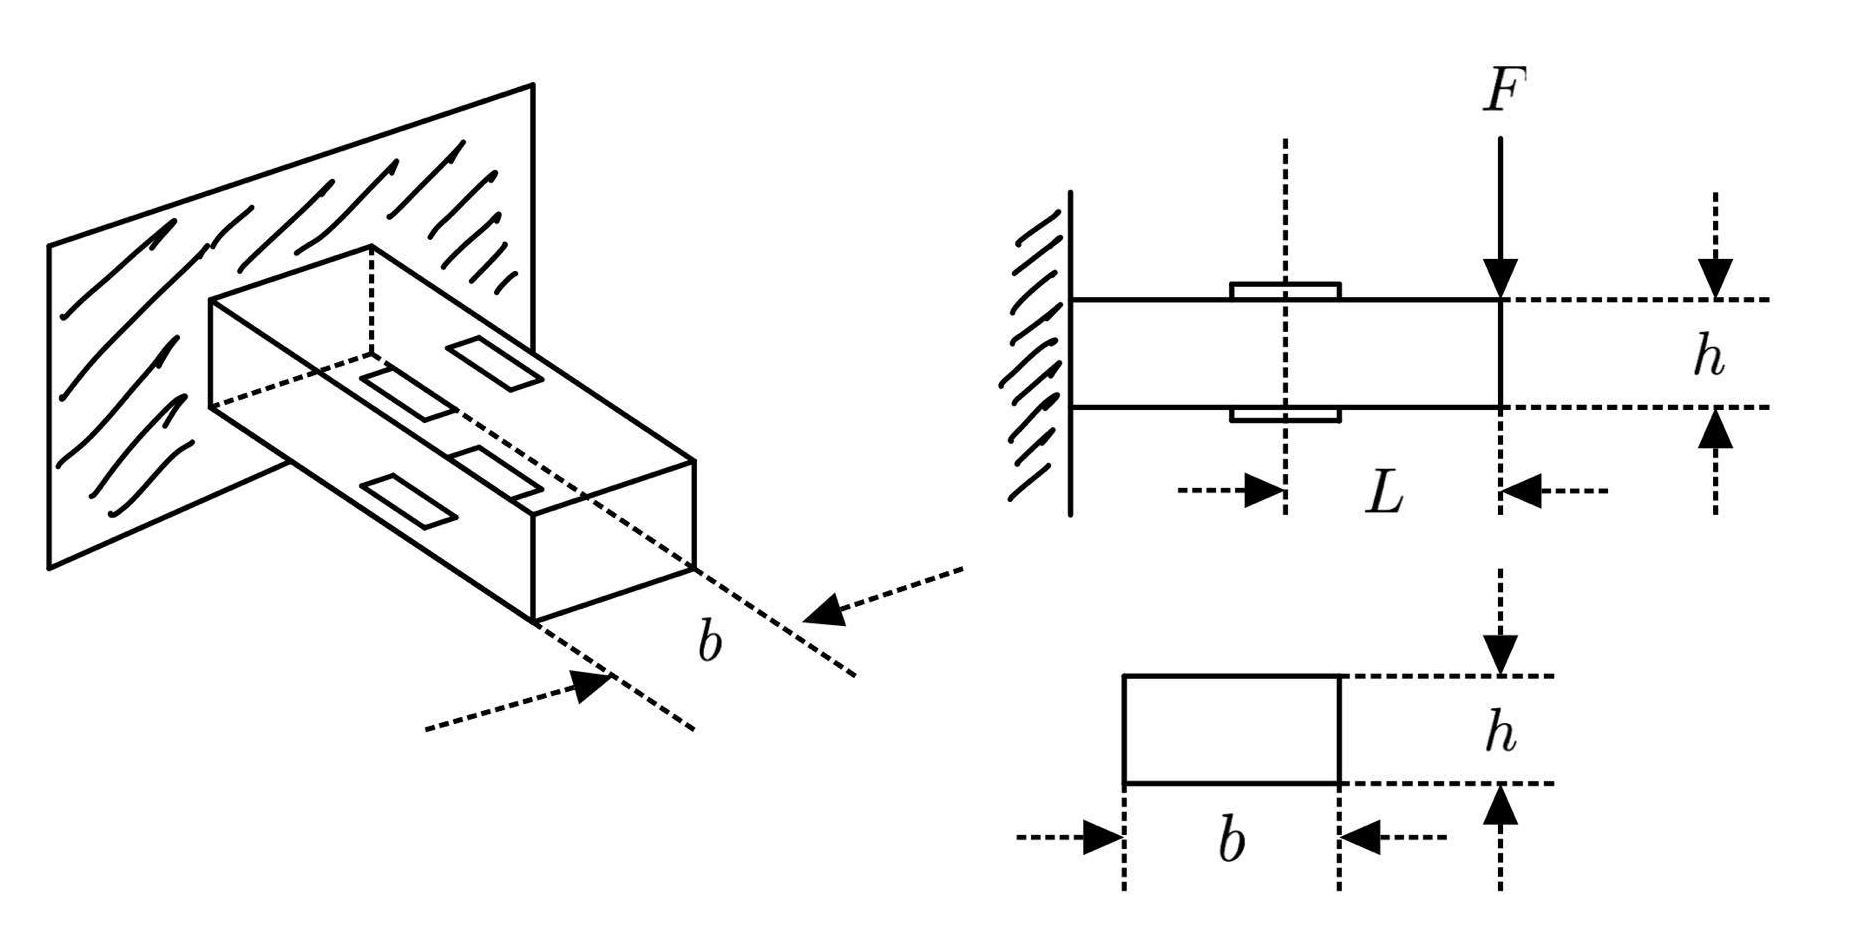

ลักษณะของคานมีความหนา $b=0\ldotp 03\;\left\lbrack \mathrm{m}\right\rbrack$ ความสูง $h=0\ldotp 022\;\left\lbrack \mathrm{m}\right\rbrack$ และค่า Flexural modulus $E=0\ldotp 69\;\left\lbrack \textrm{MPa}\right\rbrack$ 

เพื่อวัดแรงที่กระทำ เราสามารถแปลงระบบนี้ให้กลายเป็น load cell ที่มี strain gauge ทั้งหมด 4 อันติดตั้งอยู่หากจากจุดที่แรงกระทำอยู่ $L=0\ldotp 053\left\lbrack m\right\rbrack$

กำหนดให้ strain gauge ทั้ง 4 อันนั้นเป็น RS PRO Foil Strain Gauge (สามารถหา datasheet จากออนไลน์ได้) 

- จงสังเคราะห์ระบบที่แทนความสัมพันธ์ของ แรง $F$ และ ความเค้น $\varepsilon$

- จงสังเคราะห์ระบบ Wheatstone Bridge ที่ใช้ในการวัด Strain Gauge ให้กลายเป็นระบบที่เป็นเชิงเส้น ($v_i$ แปรผันแบบเชิงเส้นกับ $F$)

-  จงสังเคราะห์วงจรสำหรับการปรับแต่งสัญญาณจาก Wheatstone Bridge $v_i$เพื่อที่จะให้สัญญาณเอ้าท์พุท$v_o$ เป็นเต็มช่วง $0$ ถึง $5\;\left\lbrack \mathrm{V}\right\rbrack$

- จงเชื่อมต่อแต่ละระบบเข้าด้วยกันเพื่อให้ใช้งานด้วยกันได้ โดยจำเป็นต้องใช้ Power Supply และ LM358 ที่กำหนดให้

- ระบบที่ออกแบบต้องมีความสัมพันธ์เชิงเส้น (Linearity) โดยที่ค่า R-squared มากกว่า 0.999

- พิกัดในการวัดต้องอยู่ระหว่าง 0 - 5V เท่านั้น

- ความละเอียดในการอ่านข้อมูลต้อง <= 0.0005 [N/bit] โดยใช้อุปกรณ์ ADC ความละเอียด 10 bit ที่แรงดันไฟฟ้าอ้างอิง 5 V 

- ในการออกแบบต้องใช้ค่า Resister มาตราฐาน E24 เท่านั้น (https://asenergi.com/pdf/resistors/standard-resistor-values-e24.pdf)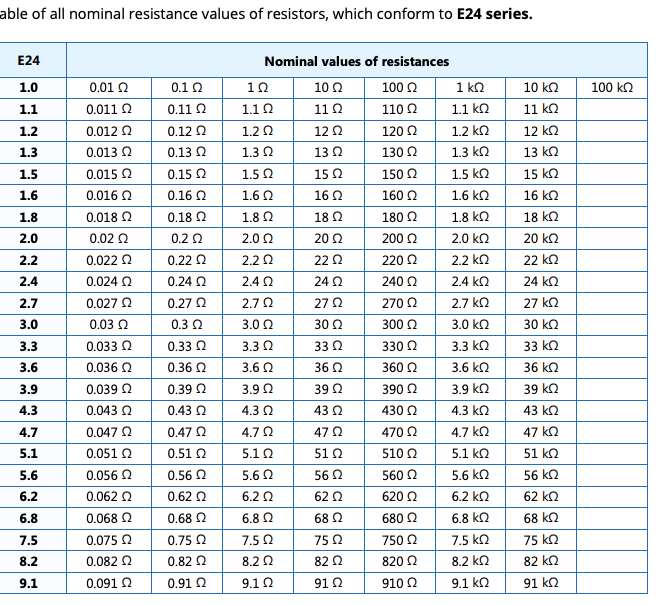

- Block Resistor ที่นักศึกษาเอามางานต้องใช้ Block ของ Foudation Library เท่านั้น (ภาพซ้าย)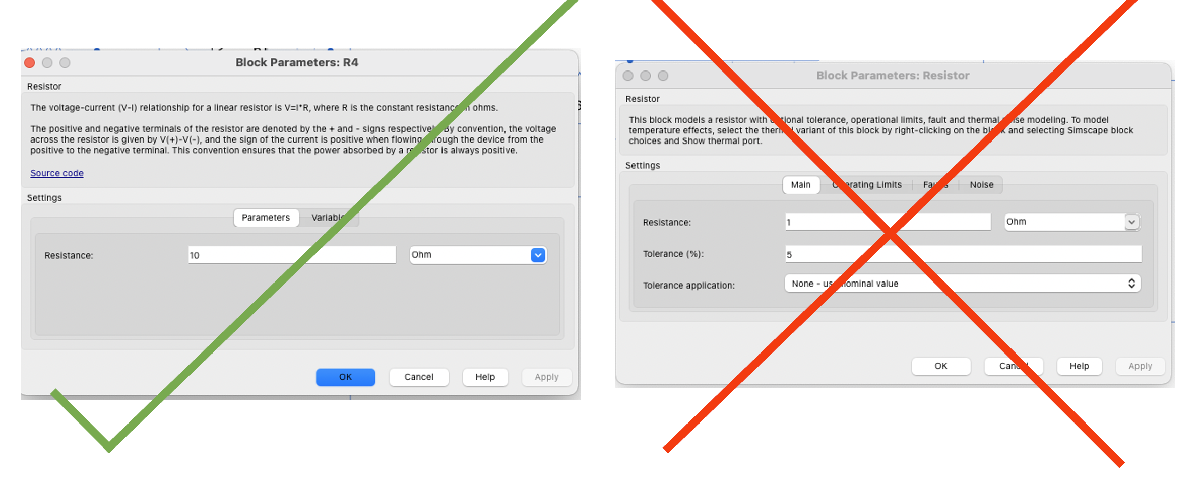

- ต้องใช้ LM358 ในการต่อวงจรเท่านั้น

- ห้ามเปลี่ยนชื่อไฟล์ model และ sub function ที่กำหนดให้

ผลลัพธ์ที่ได้นั้นควรให้ความสัมพันธ์ดังต่อไปนี้

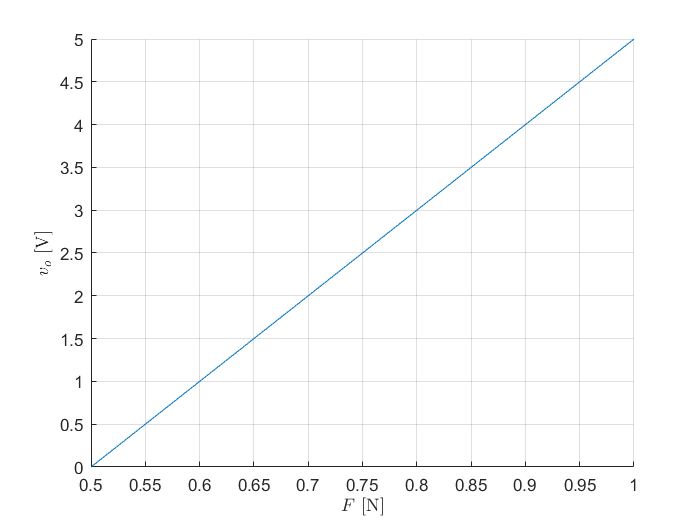

clf
f = linspace(0.5,1,2^10);
v_o = 10*(f-0.5);
ax = axes;
hold(ax,'on');
grid(ax,'on');
plot(ax,f,v_o);
xlabel(ax,'$F$ [N]','interpreter','latex');
ylabel(ax,'$v_o$ [V]','interpreter','latex');